clc; 
clear; 
close all;

%% Motor Parameters Struct
motor.Rs   = 1.1;
motor.Ld   = 14e-3;
motor.Lq   = 33e-3;
motor.PsiF = 0.368;
motor.P    = 4;
motor.pp   = motor.P / 2;
motor.J    = 1e-4;
motor.B    = 5e-5;

%% Simulation & Inverter Settings Struct
inv.Vdc       = 400;           % DC Link Voltage [V]
inv.f_carrier = 10000;         % PWM Carrier Frequency [Hz]

% Execution Sample Times
Ts_plant = 1e-6;                % Continuous plant step = 1 us (1 MHz)
Ts_curr  = 1 / inv.f_carrier;   % Current loop step = 100 us (10 kHz)
Ts_speed = 10 * Ts_curr;        % Speed loop step = 1 ms (1 kHz, 10x slower)

Tsim          = 2;              % Total time [s]
t             = 0:Ts_plant:Tsim;
N             = length(t);

% Clock Divider Decimation Ratios
ratio_curr  = round(Ts_curr / Ts_plant);   % 100 steps
ratio_speed = round(Ts_speed / Ts_plant);  % 1000 steps

%% Initial States
id      = 0;
iq      = 0;
wm      = 0;
theta_m = 0;
TL      = 0;                   % Load Torque [Nm]

%% Controller Parameters & Integral States
% 1. Outer Speed PI Controller (Tuned for RPM Error Domain)
Kp_speed    = 0.004;   
Ki_speed    = 0.5;   
e_speed_int = 0;
Q_max   = 12;              % Max q-axis reference current limit [A]
Q_min   = -12;

% Inner d-q current control uses sliding-mode control (SMC) with MTPA references.

% Voltage limits for d-q current controllers
V_max =  inv.Vdc / sqrt(3);
V_min = -inv.Vdc / sqrt(3);

% Hold state variables across multirate triggers
iq_ref = 0;
Vd_cmd = 0;
Vq_cmd = 0;
ma_sv  = 0.5;
mb_sv  = 0.5;
mc_sv  = 0.5;

%% Pre-allocate Logging Arrays
id_log      = zeros(1, N);
iq_log      = zeros(1, N);
vd_log      = zeros(1, N);
vq_log      = zeros(1, N);
va_log      = zeros(1, N);
vb_log      = zeros(1, N);
vc_log      = zeros(1, N);
Nref_log    = zeros(1, N);
rpm_log     = zeros(1, N);
Te_log      = zeros(1, N);
theta_e_log = zeros(1, N);
ma_log      = zeros(1, N);
mb_log      = zeros(1, N);
mc_log      = zeros(1, N);
carrier_log = zeros(1, N);

%% Main Simulation Loop
for k = 1:N
    % Soft torque step
    if t(k) < 1.0
        TL = 1;
    else
        TL = 5;
    end

    % 1. Compute Speed Reference Trajectory [RPM]
    [Nref] = get_speed_reference(t(k));
    
    % Feedback Signals (Convert actual rad/s motor speed to RPM)
    N_actual = wm * (60 / (2*pi));
    Nref_log(k) = Nref; 
    theta_e  = mod(motor.pp * theta_m, 2*pi); % Measured electrical angle

    % ------------------ 2. OUTER SPEED CONTROL LOOP (Every 1 ms) ------------------
    if mod(k-1, ratio_speed) == 0
        speed_error = Nref - N_actual;
        [iq_ref, e_speed_int] = ...
            pi_controller(speed_error, e_speed_int, Kp_speed, Ki_speed, Ts_speed, Q_min, Q_max);
    end
    % MTPA reference generation for the salient PMSM.
    % The speed PI output is treated as the q-axis current request; MTPA
    % computes the corresponding negative d-axis current for Lq > Ld.
    [id_ref, iq_ref] = mtpa_current_reference(iq_ref, motor, 12);

    % ------------------ 3. INNER SMC CURRENT CONTROL ------------------
    if mod(k-1, ratio_curr) == 0
        % Electrical angular speed [rad/s]
        omega_e = motor.pp * wm;

        [Vd_cmd, Vq_cmd] = sliding_mode_current_controller( ...
            id_ref, iq_ref, id, iq, omega_e, motor, inv.Vdc);

        % ------------------ 4. MODULATION GENERATION ------------------
        [va_cmd, vb_cmd, vc_cmd] = dq2abc(Vd_cmd, Vq_cmd, theta_e);
        ma_sin = (va_cmd / V_max + 1) / 2;
        mb_sin = (vb_cmd / V_max + 1) / 2;
        mc_sin = (vc_cmd / V_max + 1) / 2;

        % Apply SVPWM Min-Max Common-Mode Offset Injection
        [ma_sv, mb_sv, mc_sv] = svpwm_offset(ma_sin, mb_sin, mc_sin);
    end

    % ------------------ 5. PWM INVERTER (Every 1 us step) ------------------
    [va, vb, vc, carrier] = pwm_inverter_unipolar(ma_sv, mb_sv, mc_sv, t(k), inv);

    % Log Modulation and Control Signals
    ma_log(k)      = ma_sv;
    mb_log(k)      = mb_sv;
    mc_log(k)      = mc_sv;
    carrier_log(k) = carrier;
    
    % Log Current States
    vd_log(k)  = Vd_cmd;   % Storing raw PI controller output Vd
    vq_log(k)  = Vq_cmd;
    id_log(k)      = id;
    iq_log(k)      = iq;
    va_log(k)      = va;
    vb_log(k)      = vb;
    vc_log(k)      = vc;   
    rpm_log(k)     = N_actual;
    theta_e_log(k) = theta_e;

    % ------------------ 6. EXECUTE PMSM STEP (Every 1 us step) ------------------
    [id_next, iq_next, wm_next, theta_m_next, Te, vd, vq] = ...
        pmsm_step(va, vb, vc, TL, id, iq, wm, theta_m, Ts_plant, motor);

    % Log Computed Outputs
    Te_log(k) = Te;
    vd_log(k) = vd;
    vq_log(k) = vq;

    % State Updates for Next Time Step
    id      = id_next;
    iq      = iq_next;
    wm      = wm_next;
    theta_m = theta_m_next;
end

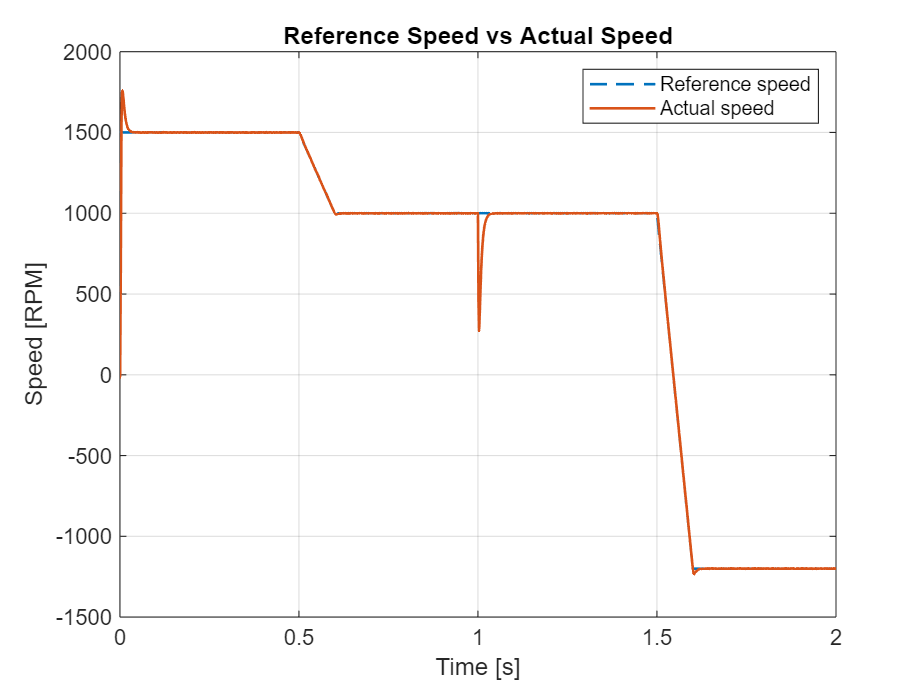

%% 7. Reference Speed vs Actual Speed
figure('Name', 'Reference and Actual Speed', 'NumberTitle', 'off');
plot(t, Nref_log, '--', 'LineWidth', 1.2); hold on;
plot(t, rpm_log, 'LineWidth', 1.2);
grid on; xlabel('Time [s]'); ylabel('Speed [RPM]');
legend('Reference speed', 'Actual speed'); title('Reference Speed vs Actual Speed');

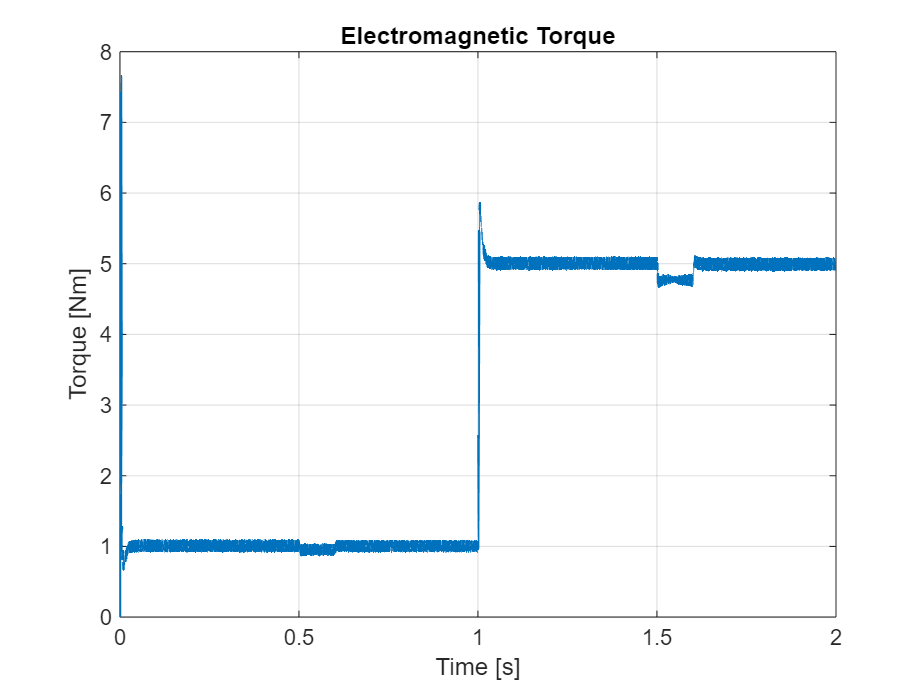

%% 8. Electromagnetic Torque
figure('Name', 'Electromagnetic Torque', 'NumberTitle', 'off');
plot(t, Te_log, 'LineWidth', 1.2);
grid on; xlabel('Time [s]'); ylabel('Torque [Nm]');
title('Electromagnetic Torque');

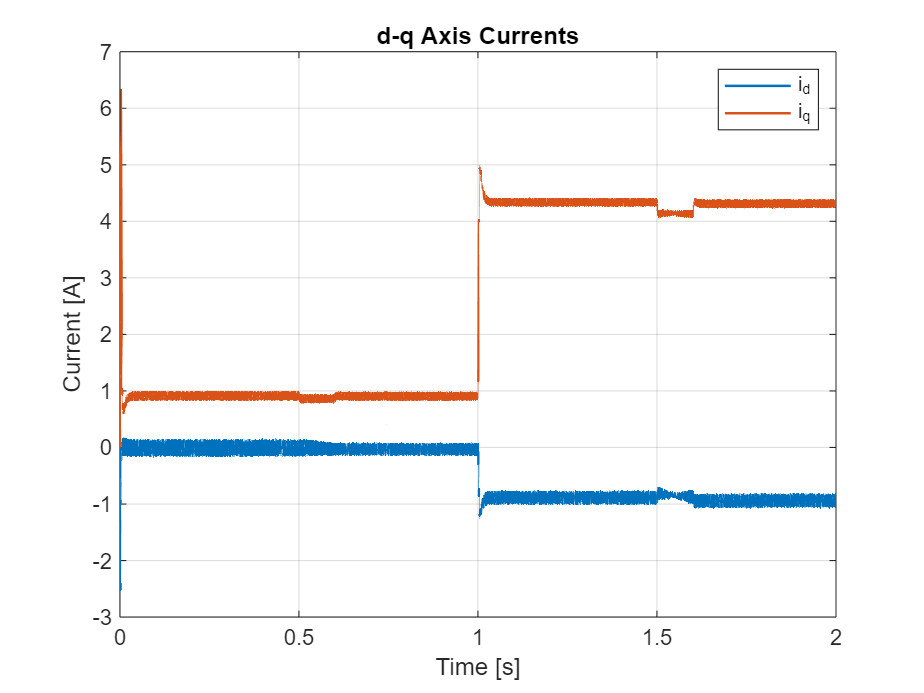

%% 9. d-q Axis Currents
figure('Name', 'd-q Axis Currents', 'NumberTitle', 'off');
plot(t, id_log, 'LineWidth', 1.1); hold on;
plot(t, iq_log, 'LineWidth', 1.1);
grid on; xlabel('Time [s]'); ylabel('Current [A]');
legend('i_d', 'i_q'); title('d-q Axis Currents');

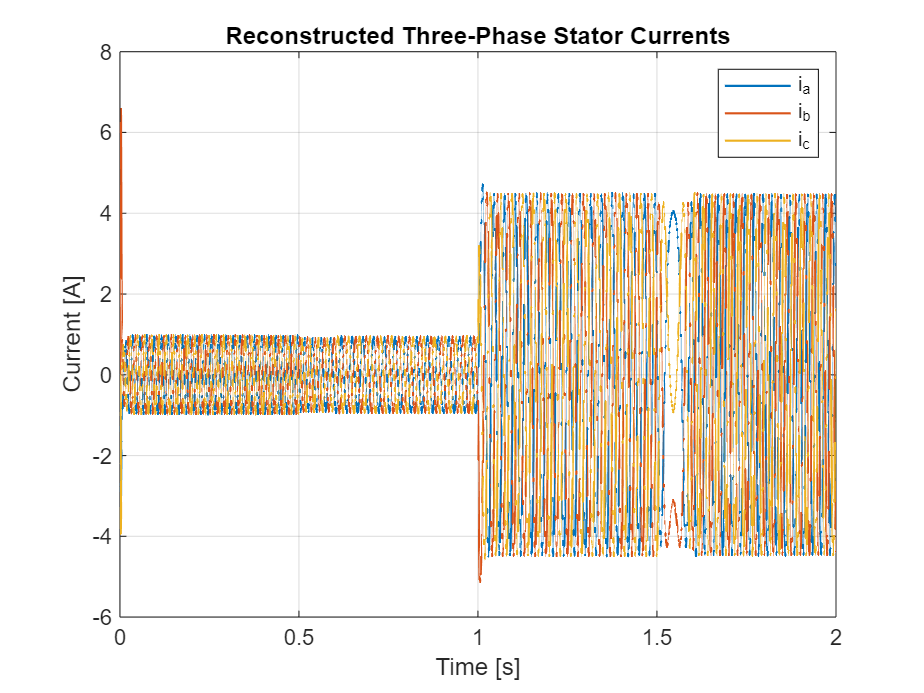

%% 10. Three-Phase Stator Currents
ia_log = zeros(1, N); ib_log = zeros(1, N); ic_log = zeros(1, N);
for k = 1:N
    [ia_log(k), ib_log(k), ic_log(k)] = dq2abc(id_log(k), iq_log(k), theta_e_log(k));
end
figure('Name', 'Three-Phase Stator Currents', 'NumberTitle', 'off');
plot(t, ia_log, 'LineWidth', 1.0); hold on;
plot(t, ib_log, 'LineWidth', 1.0);
plot(t, ic_log, 'LineWidth', 1.0);
grid on; xlabel('Time [s]'); ylabel('Current [A]');
legend('i_a', 'i_b', 'i_c'); title('Reconstructed Three-Phase Stator Currents');

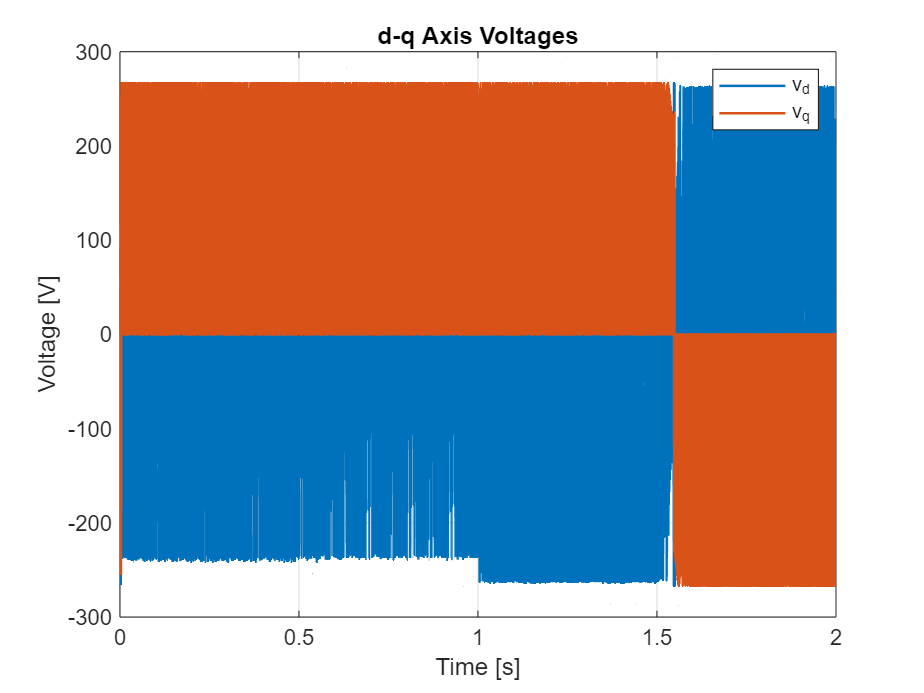

%% 11. d-q Axis Voltages
figure('Name', 'd-q Axis Voltages', 'NumberTitle', 'off');
plot(t, vd_log, 'LineWidth', 1.1); hold on;
plot(t, vq_log, 'LineWidth', 1.1);
grid on; xlabel('Time [s]'); ylabel('Voltage [V]');
legend('v_d', 'v_q'); title('d-q Axis Voltages');

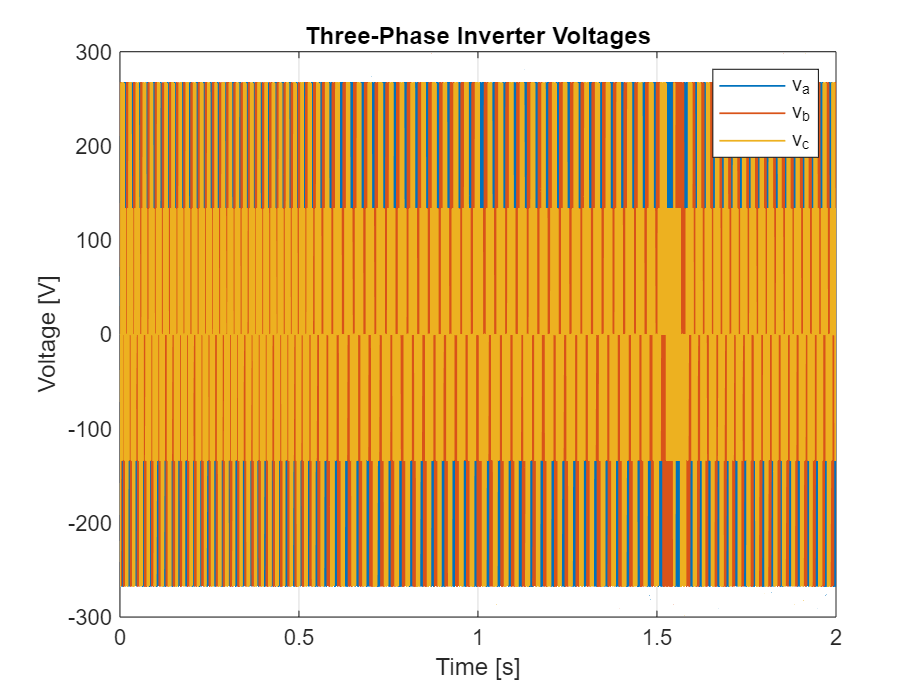

%% 12. Three-Phase Inverter Voltages
figure('Name', 'Three-Phase Inverter Voltages', 'NumberTitle', 'off');
plot(t, va_log, 'LineWidth', 0.8); hold on;
plot(t, vb_log, 'LineWidth', 0.8);
plot(t, vc_log, 'LineWidth', 0.8);
grid on; xlabel('Time [s]'); ylabel('Voltage [V]');
legend('v_a', 'v_b', 'v_c'); title('Three-Phase Inverter Voltages');

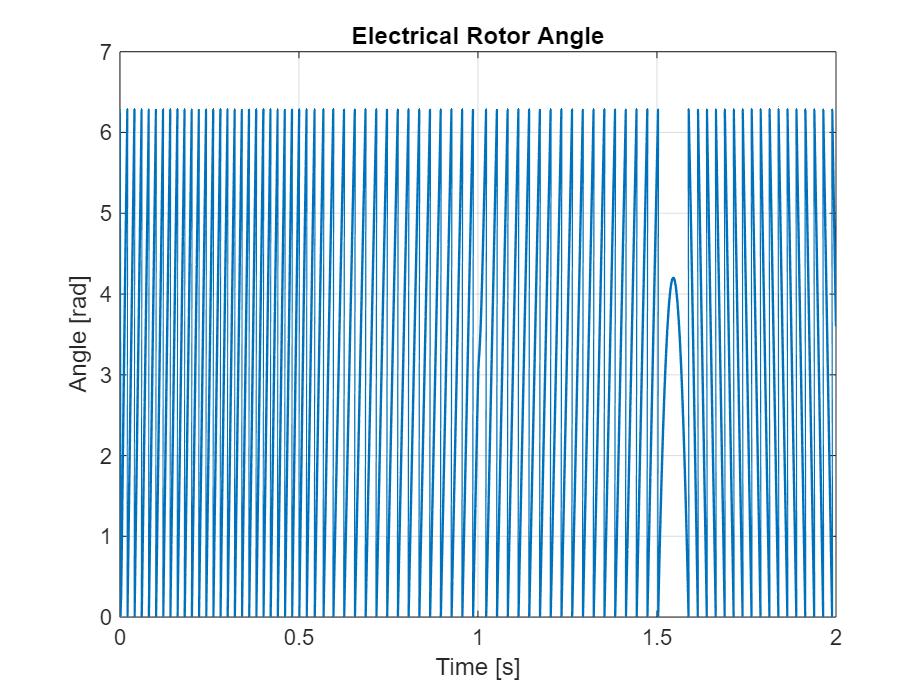

%% 13. Electrical Rotor Angle
figure('Name', 'Electrical Rotor Angle', 'NumberTitle', 'off');
plot(t, theta_e_log, 'LineWidth', 1.1);
grid on; xlabel('Time [s]'); ylabel('Angle [rad]');
title('Electrical Rotor Angle');

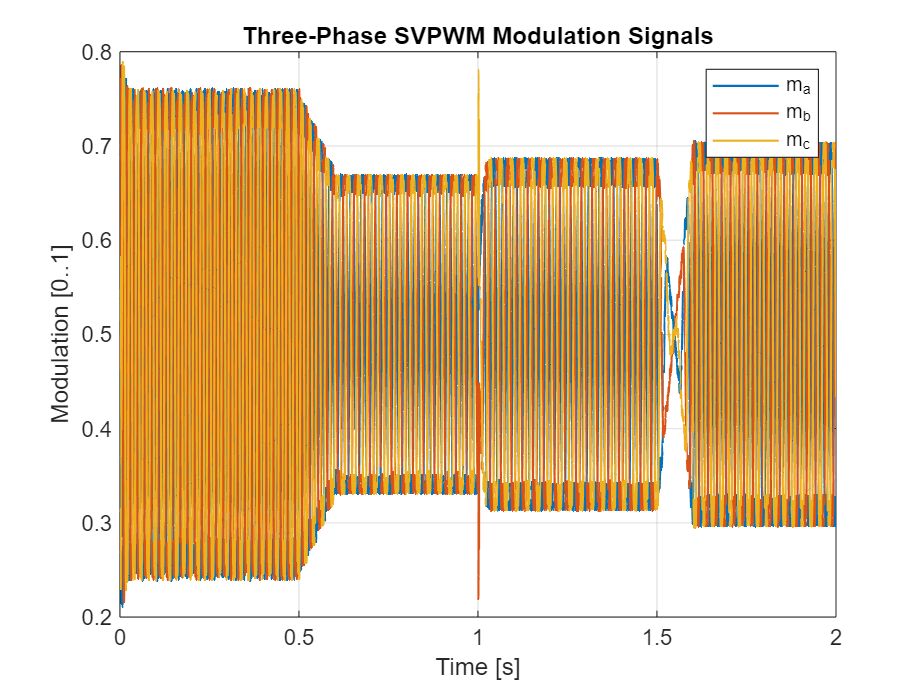

%% 14. Three-Phase SVPWM Modulation Signals
figure('Name', 'Three-Phase SVPWM Modulation Signals', 'NumberTitle', 'off');
plot(t, ma_log, 'LineWidth', 1.0); hold on;
plot(t, mb_log, 'LineWidth', 1.0);
plot(t, mc_log, 'LineWidth', 1.0);
grid on; xlabel('Time [s]'); ylabel('Modulation [0..1]');
legend('m_a', 'm_b', 'm_c'); title('Three-Phase SVPWM Modulation Signals');

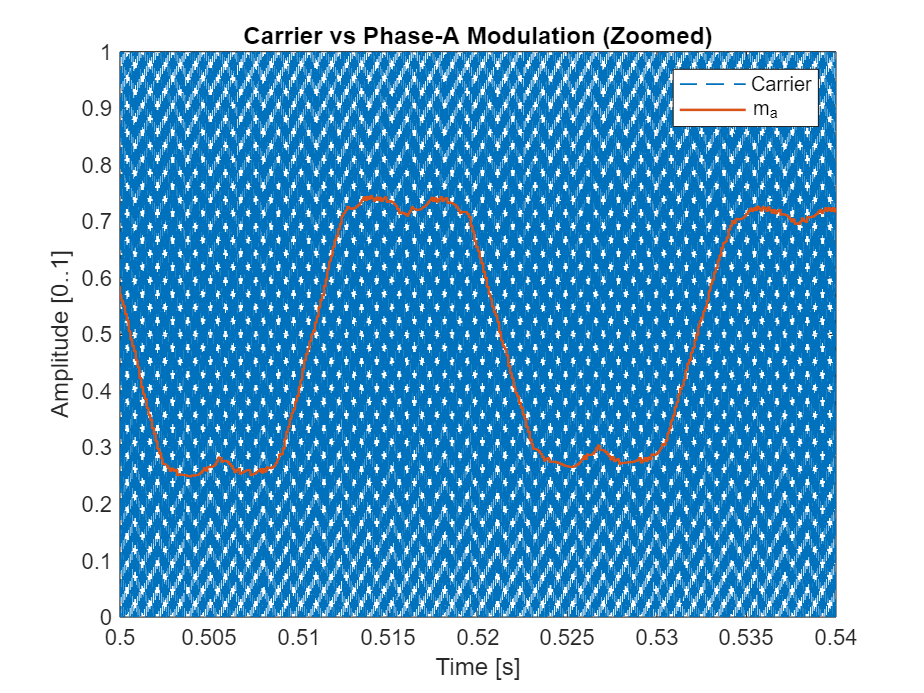

%% 15. Carrier vs Phase-A Modulation (Zoomed)
figure('Name', 'Carrier vs Phase-A Modulation', 'NumberTitle', 'off');
plot(t, carrier_log, '--', 'LineWidth', 0.8); hold on;
plot(t, ma_log, 'LineWidth', 1.1);
grid on; xlabel('Time [s]'); ylabel('Amplitude [0..1]');
xlim([0.5, 0.54]); legend('Carrier', 'm_a');
title('Carrier vs Phase-A Modulation (Zoomed)');

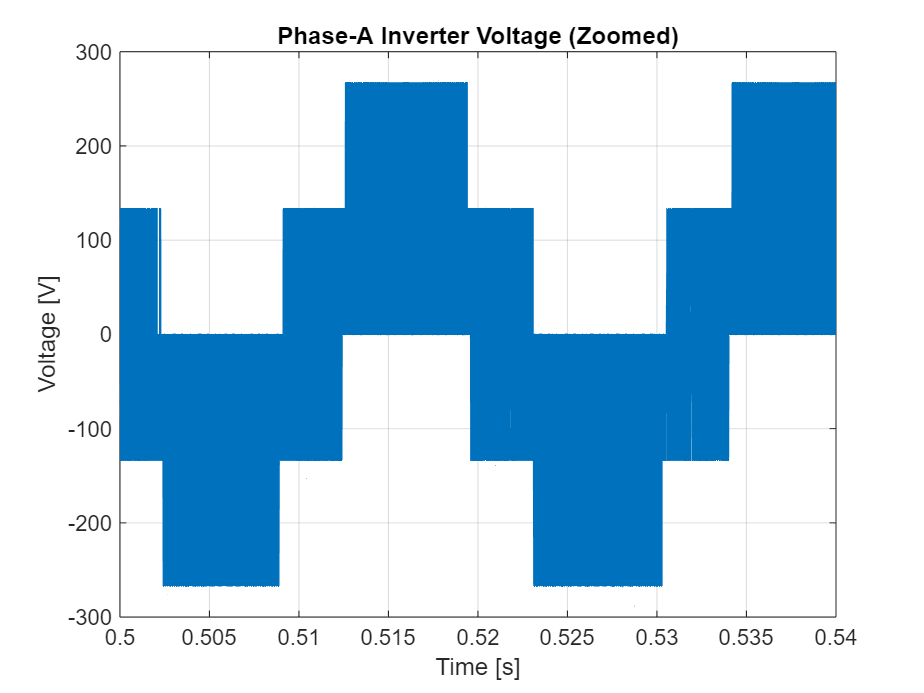

%% 16. Phase-A Inverter Voltage (Zoomed)
figure('Name', 'Phase-A Inverter Voltage', 'NumberTitle', 'off');
plot(t, va_log, 'LineWidth', 0.8);
grid on; xlabel('Time [s]'); ylabel('Voltage [V]');
xlim([0.5, 0.54]); title('Phase-A Inverter Voltage (Zoomed)');

%% ======================= FUNCTIONS =======================
% GET_SPEED_REFERENCE Generates a smooth, piecewise continuous speed trajectory in RPM
function Nref = get_speed_reference(t)

    N1 = 1500;  % First speed (RPM)
    N2 = 1000;  % Second speed (RPM)
    N3 = -1200;  % Third speed (RPM)

    t1 = 0.5;   % Start ramp down
    t2 = 0.6;   % End ramp down
    t3 = 1.5;   % Start ramp up
    t4 = 1.6;   % End ramp up

    if t < t1
        Nref = N1;

    elseif t < t2
        % Ramp from 1500 to 1000 RPM
        Nref = N1 + (N2-N1)*(t-t1)/(t2-t1);

    elseif t < t3
        Nref = N2;

    elseif t < t4
        % Ramp from 1000 to 1200 RPM
        Nref = N2 + (N3-N2)*(t-t3)/(t4-t3);

    else
        Nref = N3;
    end

end

% Reusable Single Discrete PI Controller Function with Anti-Windup Clamping
function [u, e_int_next] = pi_controller(error, e_int, Kp, Ki, Ts, u_min, u_max)
    e_int_next = e_int + error * Ts;
    u_unsat    = Kp * error + Ki * e_int_next;
    u          = max(min(u_unsat, u_max), u_min);
    
    if u ~= u_unsat
        e_int_next = e_int_next - error * Ts;
    end
end


% MTPA current-reference generator for an IPMSM/salient PMSM.
function [id_ref, iq_ref_limited] = mtpa_current_reference(iq_request, motor, Imax)
    % For the given motor model: Ld = 14 mH, Lq = 33 mH, so Lq > Ld.
    % This expression gives the MTPA d-axis current for a requested iq.
    % iq_request remains the q-axis current request from the speed PI.
    Ld = motor.Ld;
    Lq = motor.Lq;
    psi_f = motor.PsiF;

    iq_ref_limited = max(-Imax, min(Imax, iq_request));
    deltaL = Lq - Ld;

    if deltaL <= 1e-12
        % For a non-salient/SPMSM, use id*=0.
        id_ref = 0;
    else
        id_ref = (psi_f - sqrt(psi_f^2 + 4*deltaL^2*iq_ref_limited^2)) ...
                 / (2*deltaL);
    end

    % Enforce total stator-current magnitude limit.
    id_ref = max(-sqrt(max(Imax^2 - iq_ref_limited^2, 0)), ...
                  min(0, id_ref));
end

% Sliding-mode d-q current controller with boundary-layer saturation.
function [vd_ref, vq_ref] = sliding_mode_current_controller( ...
    id_ref, iq_ref, id, iq, omega_e, motor, Vdc)

    Rs = motor.Rs;
    Ld = motor.Ld;
    Lq = motor.Lq;
    psi_f = motor.PsiF;

    % Initial tuning values; tune using current tracking response.
    kd = 3000;       % d-axis reaching gain [A/s]
    kq = 3000;       % q-axis reaching gain [A/s]
    phi_d = 0.5;     % d-axis boundary layer [A]
    phi_q = 0.5;     % q-axis boundary layer [A]

    ed = id_ref - id;
    eq = iq_ref - iq;
    sat_d = max(-1, min(1, ed/phi_d));
    sat_q = max(-1, min(1, eq/phi_q));

    % Equivalent voltage terms cancel nominal PMSM dynamics.
    vd_raw = Rs*id - omega_e*Lq*iq + Ld*kd*sat_d;
    vq_raw = Rs*iq + omega_e*(Ld*id + psi_f) + Lq*kq*sat_q;

    % Limit voltage vector to the linear SVPWM range.
    Vmax = Vdc/sqrt(3);
    Vmag = sqrt(vd_raw^2 + vq_raw^2);
    if Vmag > Vmax
        scale = Vmax/Vmag;
        vd_ref = vd_raw*scale;
        vq_ref = vq_raw*scale;
    else
        vd_ref = vd_raw;
        vq_ref = vq_raw;
    end
end


% SVPWM Offset Generator
function [ma_sv, mb_sv, mc_sv] = svpwm_offset(ma, mb, mc)
    v_max    = max([ma, mb, mc]);
    v_min    = min([ma, mb, mc]);
    v_offset = 0.5 * (1 - (v_max + v_min));
    ma_sv    = ma + v_offset;
    mb_sv    = mb + v_offset;
    mc_sv    = mc + v_offset;
end

% Unipolar PWM Generator
function [va, vb, vc, carrier] = pwm_inverter_unipolar(ma, mb, mc, current_time, inv)
    Vdc       = inv.Vdc;
    f_carrier = inv.f_carrier;
    T_carrier = 1 / f_carrier;
    carrier   = 2 * abs(mod(current_time / T_carrier, 1) - 0.5);
    
    S_a = ma > carrier;
    S_b = mb > carrier;
    S_c = mc > carrier;
    
    va = (Vdc / 3) * (2*S_a - S_b - S_c);
    vb = (Vdc / 3) * (2*S_b - S_a - S_c);
    vc = (Vdc / 3) * (2*S_c - S_a - S_b);
end

% Core PMSM Integration Step Function
function [id_next, iq_next, wm_next, theta_m_next, Te, vd, vq] = pmsm_step(va, vb, vc, TL, id, iq, wm, theta_m, Ts, motor)
    Rs   = motor.Rs;
    Ld   = motor.Ld;
    Lq   = motor.Lq; 
    PsiF = motor.PsiF; 
    pp   = motor.pp;
    J    = motor.J;
    B    = motor.B;
    
    theta_e = mod(pp * theta_m, 2*pi);
    we      = pp * wm;
    
    [vd, vq] = abc2dq(va, vb, vc, theta_e);
    did_dt   = (vd - Rs*id + we*Lq*iq) / Ld;
    diq_dt   = (vq - Rs*iq - we*(Ld*id + PsiF)) / Lq;
    Te       = 1.5 * pp * (PsiF*iq + (Ld - Lq)*id*iq);
    dwm_dt   = (Te - TL - B*wm) / J;
    
    id_next      = id      + Ts * did_dt;
    iq_next      = iq      + Ts * diq_dt;
    wm_next      = wm      + Ts * dwm_dt;
    theta_m_next = theta_m + Ts * wm;
end

% Coordinate Transformations
function [d, q] = abc2dq(a, b, c, theta_e)
    valpha = (2/3) * (a - 0.5*b - 0.5*c);
    vbeta  = (2/3) * (sqrt(3)/2 * (b - c));
    d      =  valpha * cos(theta_e) + vbeta * sin(theta_e);
    q      = -valpha * sin(theta_e) + vbeta * cos(theta_e);
end

function [a, b, c] = dq2abc(d, q, theta_e)
    valpha = d * cos(theta_e) - q * sin(theta_e);
    vbeta  = d * sin(theta_e) + q * cos(theta_e);
    a      = valpha;
    b      = -0.5 * valpha + (sqrt(3)/2) * vbeta;
    c      = -0.5 * valpha - (sqrt(3)/2) * vbeta;
end
